# Create and Customize a 3-D Surface and Contour Plot

`surfc` creates a surface plot with a contour plot representing the surface underneath.

### Create Surface Data

We can generate the MATLAB logo, which is the L-shaped membrane using the built-in function `membrane(k),` the k-th eigenfunction of the L-shaped membrane. Select an eigenfunction to visualize.

eigenfunction = 1;
L = 100*membrane(eigenfunction,100);

### Basic Surface with Contour Plot

View the surface generated from the membrane function and the contour underneath. 

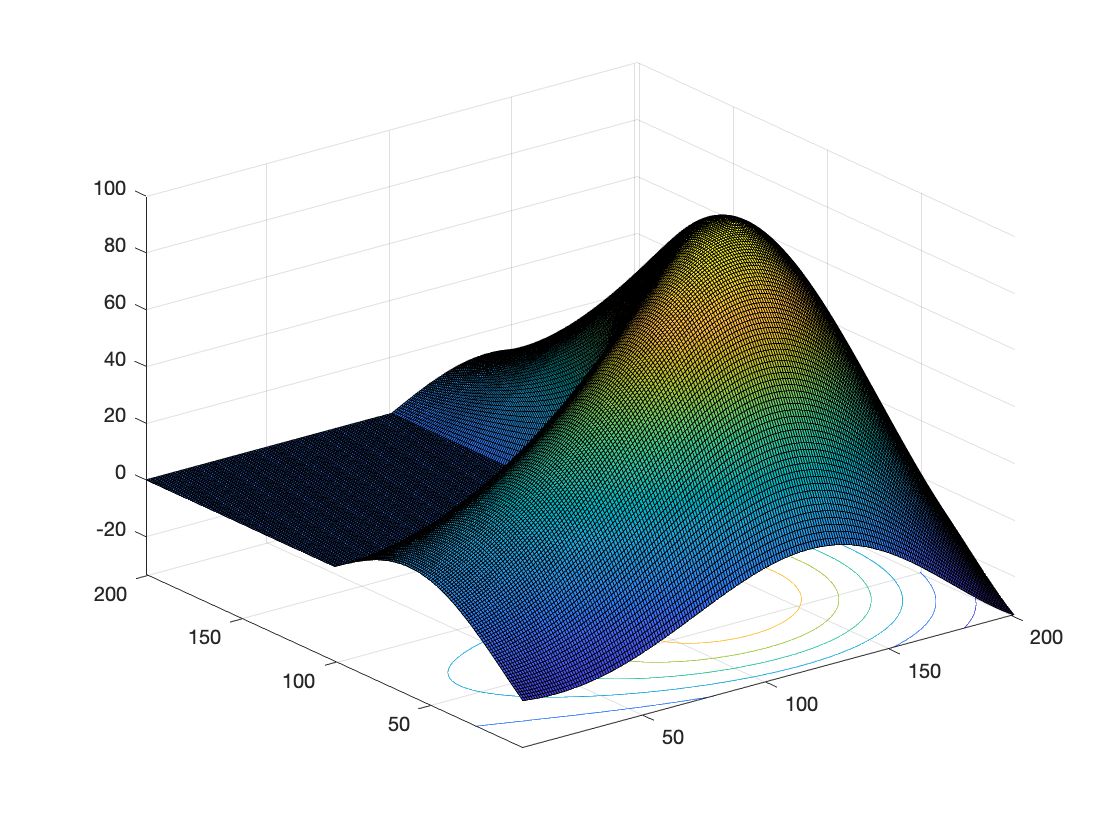

surfc(L);

## Customization

### Change Surface and Axis Appearance

The output of `surfc` contains both a Surface and Contour object at index 1 and 2 respectively. Access the *EdgeColor* property of the Surface object using dot notation and modify its properties.

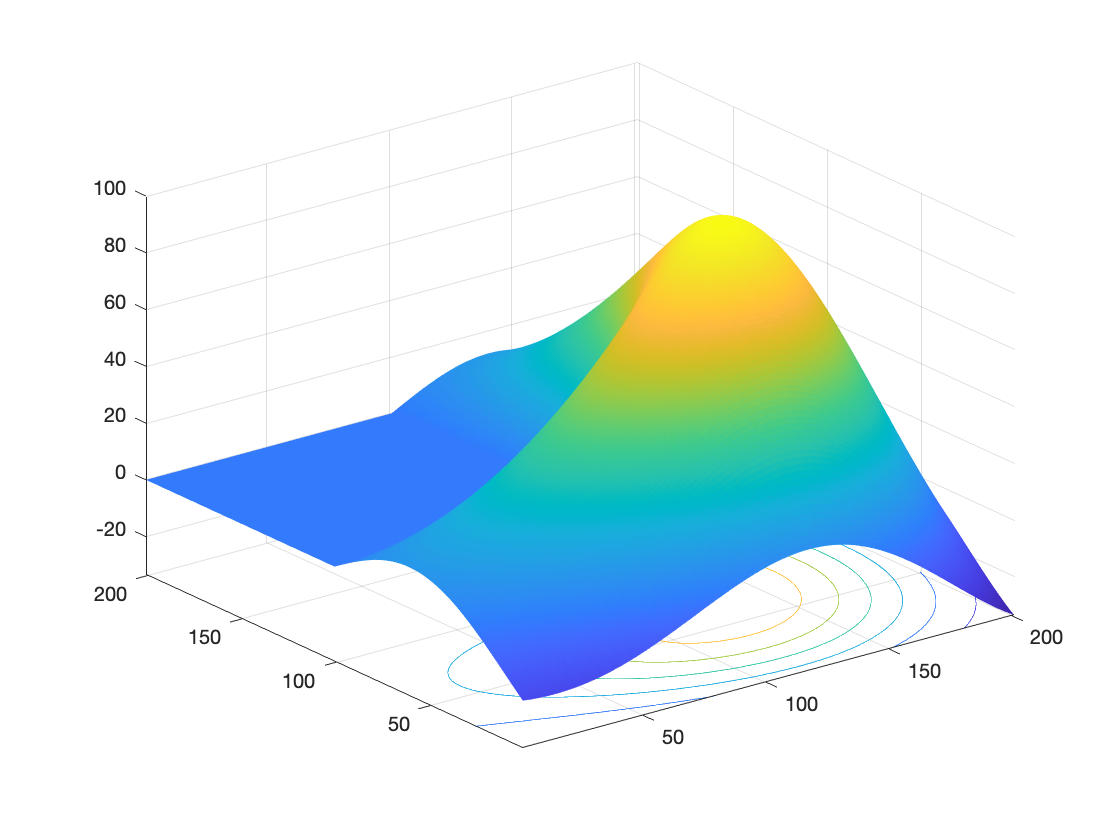

s = surfc(L);
s(1).EdgeColor = "none";      % Specify the EdgeColor of the Surface

### Change Chart Colormap

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. Specify a different colormap to use in `surfc`.

colormap("parula"); % Specify colormap

### Change Contour Appearance and Add Colorbar

Change the *LevelStep* property to modify the spacing between contour lines for greater or less detail. Modify the *LineWidth* of the contour lines for better visibility. Use a colorbar as a legend, add axes labels and a title.

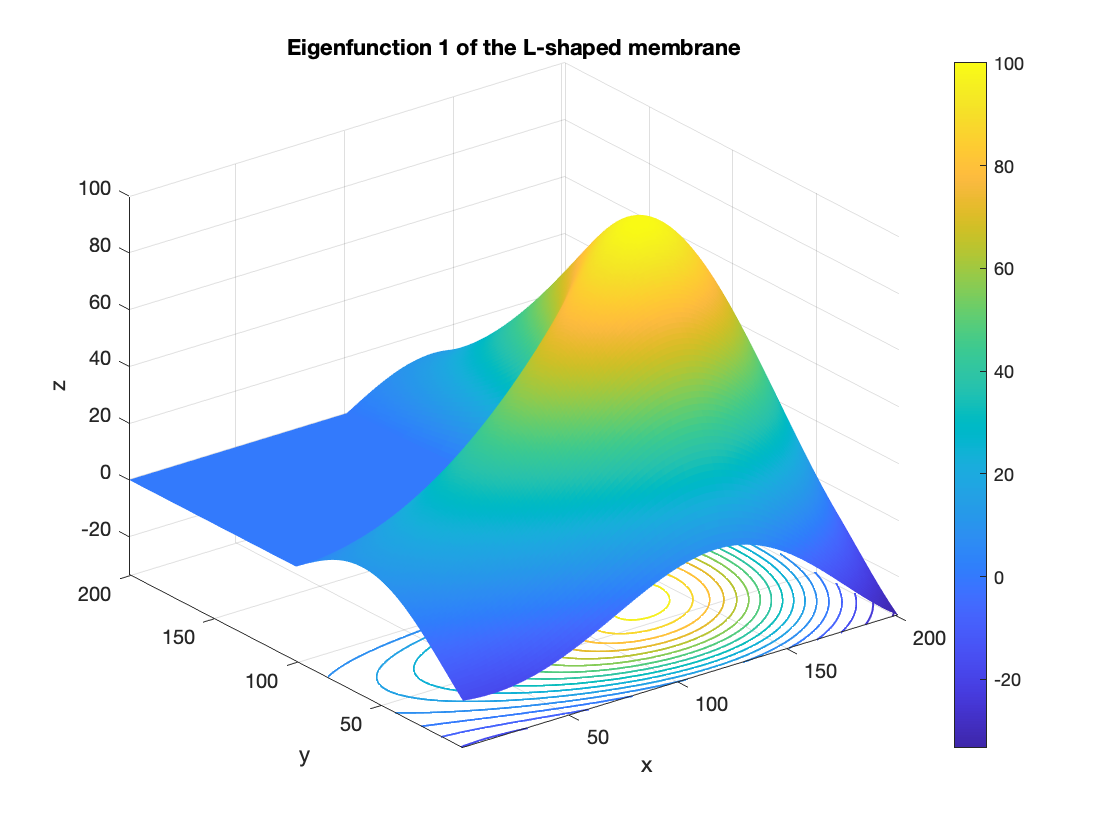

s(2).LevelStep =8;  % Specify the line spacing
s(2).LineWidth =1; % Specify the line width

colorbar
xlabel("x"); ylabel("y"); zlabel("z");
title(sprintf("Eigenfunction %d of the L-shaped membrane",...
    eigenfunction))

## **Additional Information**

### **Get All Surface and Contour Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Surface or Contour, uncomment the following code. View or modify these properties using dot notation.

% get(s(1)) % Surface
% get(s(2)) % Contour

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[surfc](https://www.mathworks.com/help/matlab/ref/surfc.html)

Copyright (c) 2021, The MathWorks, Inc.